# Impact of IOs, IWs, and tides and on the different metrics considered in this study.

Here we study the impact of wave like motions, which do no lead to any particle dispersion, on the different metrics considered here.

In particular, we try to look at the impact that changing the shape in the wavenumber spectrum of these waves has. There is no theory for how the IWs motions are shaped in wavenumber space. 

clear all
close all 

% load some model data 
d = 10; 

distance = [10,15]*1e3;

i = 1; 
[mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, ...
    mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));

depth = -1.4749e+03

    
% get the velocity from forward differencing (will be important for structure functions)
Unew = nan*mod_traj(i).X;
Vnew = nan*mod_traj(i).X;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 

mod_traj(i).U = Unew; 
mod_traj(i).V = Vnew; 

mod_traj(i).U(mod_traj(i).U==-999) = NaN;
mod_traj(i).V(mod_traj(i).V==-999) = NaN;
mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
mod_traj(i).X(mod_traj(i).X>360-70) = NaN;

## Add IOs with different props

We will consider adding a model of the kind

x_i -> A(sinft, cosft-1)

x_j -> (A+B g(t))(sinft, cosft-1)

where A is a random number, and B is also a random number. A is representative of the radius of the inertial oscialltions, but is same for both the floats in a pair. B g(t) models the growing difference in radius of IOs as the floats in a pair separate. 

g(t) is a function of time, which is 0 at t=0 and 1 at large t. Here we chose to model this as (1-exp(-ct)). This is an arbitrary choice, since we don't actually know what this function looks like. When g(t) is zero both particles move in the same IOs, and have no relative motion in the IO frequency. When g(t) is 1 the particles move relative to each other with in a circle with radius B. 

We can also set g( r), instead of a function of time and see the impact it has. Setting it as a function of separation provides more control on the spatial spectrum. 

f = 2*2*pi/(1)*sind(-55); % in units of per day

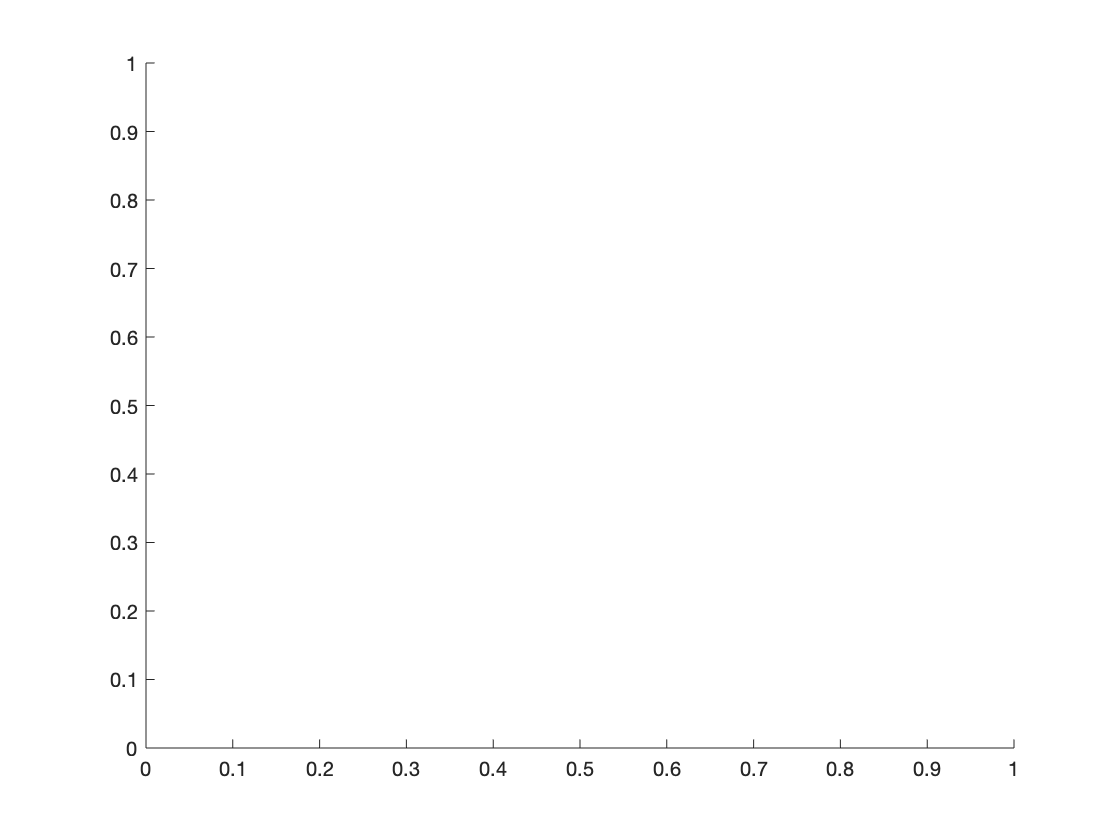

colors = get(gca,'Colororder');

mod_sep_orig = model_sep_calcs_w_NIWs(mod_traj, distance, f, 0,0,0,0);

% Add IOs with temporally changing IOs
% A = radius of IOs (degrees) 
% B = relative radius of IOs (degrees)
% C = decorrelation rate (1/days) 

mod_sep_time = model_sep_calcs_w_NIWs(mod_traj, distance, f, 1.5/110,1.5/110, 1/20, 1);

% Add IOs with spatially changing IOs
% A = radius of IOs (degrees) 
% B = relative radius of IOs (degrees)
% C = power law behavior of IO radius as a function of space
% If we want the largest difference in relative IOs to be X, then we set B
% = X/(r_l^C), where r_L = 100e3. 
% so if X = 2/110, when a=2/3, then B = (2/110)/(100e3^(2/3)) = 8.5e-6
mod_sep_space = model_sep_calcs_w_NIWs(mod_traj, distance, f, 1.5/110, (3.0/110)/(50e3^(0.5)), 0.5, 3, 50e3);
%mod_sep_space = model_sep_calcs_w_NIWs(mod_traj, distance, f, 1.5/110, (3.1/110)/(100e3^(0.36)), 0.36, 3, 100e3);

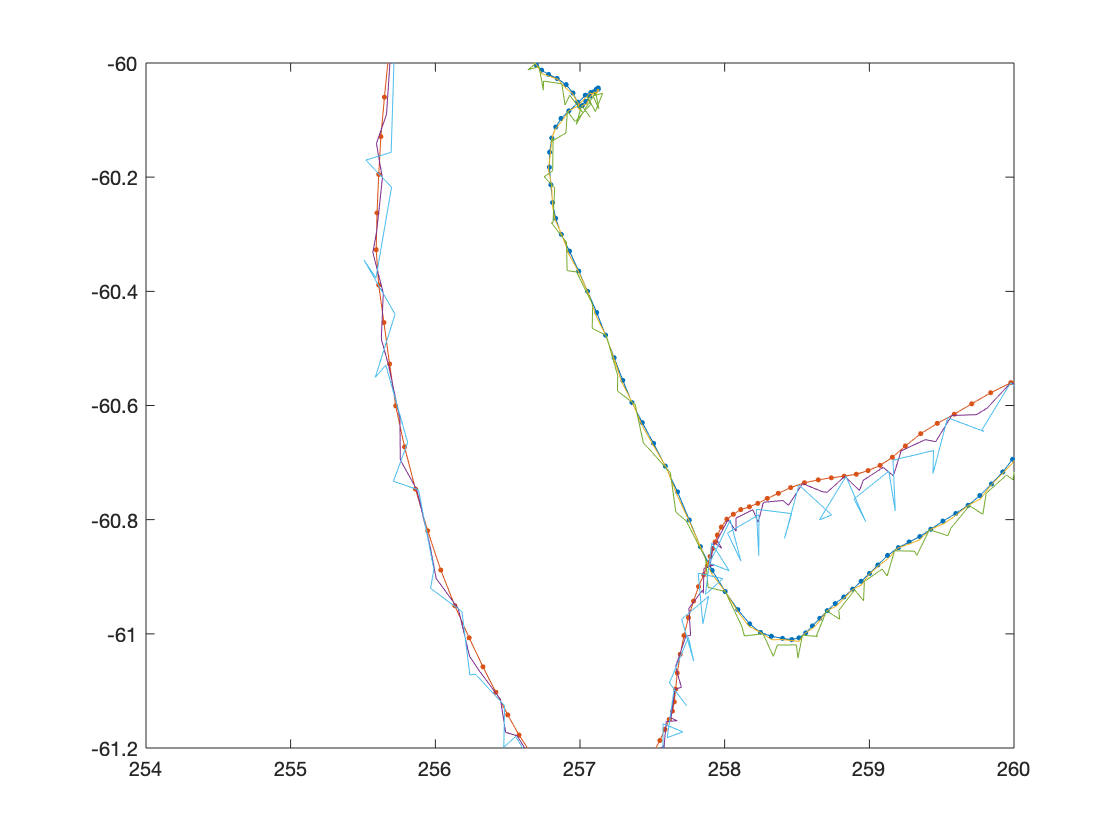

% Plot some trajectories to see what adding the IOs does
figure
n=50;
plot(mod_sep_orig.sep(n).X1, mod_sep_orig.sep(n).Y1, '.-')
hold all
plot(mod_sep_orig.sep(n).X2, mod_sep_orig.sep(n).Y2, '.-')

plot(mod_sep_time.sep(n).X1, mod_sep_time.sep(n).Y1)
plot(mod_sep_time.sep(n).X2, mod_sep_time.sep(n).Y2)

plot(mod_sep_space.sep(n).X1, mod_sep_space.sep(n).Y1)
plot(mod_sep_space.sep(n).X2, mod_sep_space.sep(n).Y2)

axis([254 260 -61.2 -60])

%% first define the distance axis 
gamma = 1.4;
dist_bin(1) = 1000; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>800*10^3,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));

flag_1time = 1;

## Check if the right spatial pattern has been imposed on IOs

for i =1:length(mod_sep_orig.sep)
    dr_time(:,i) = abs(mod_sep_orig.sep(i).dist - mod_sep_time.sep(i).dist);
    dr_space(:,i) = abs(mod_sep_orig.sep(i).dist - mod_sep_space.sep(i).dist);
    r(:,i) = mod_sep_orig.sep(i).dist;
end

for i = 1:length(dist_axis)
    id = find(r>=dist_bin(i) & r<dist_bin(i+1));
    
    drmean_time(i) = nanmean(dr_time(id));
    drmean_space(i) = nanmean(dr_space(id));

end

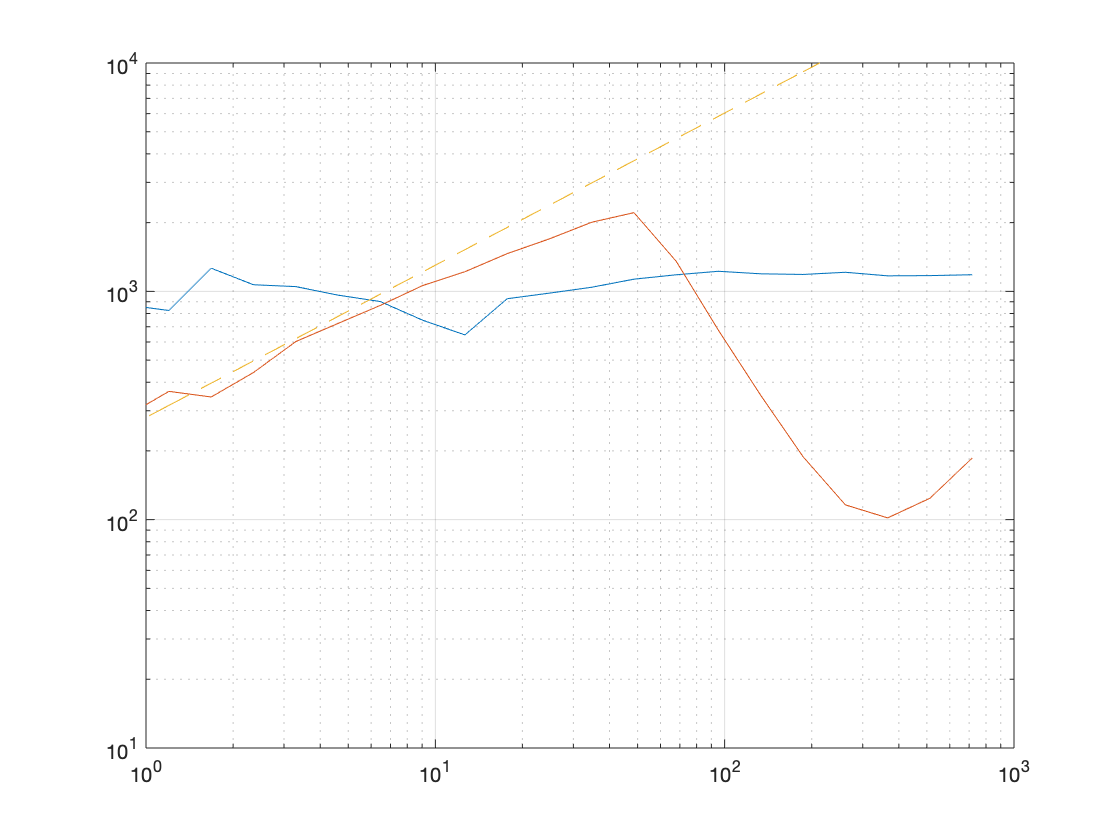

% Plot of spatial dependence of relative magniture
figure
loglog(dist_axis/1e3, drmean_time )
hold all
loglog(dist_axis/1e3, drmean_space)
loglog(dist_axis/1e3, 0.5*1e3*(6*((1/35e3*dist_axis).^(2/3))),'--')

axis([1 1000 10 1e4])
grid

## FSLE

%% FSLE Orig
fsle_mod_orig = fsle_model(mod_sep_orig.sep, dist_bin, 1, flag_1time); 

% FSLE for time model
fsle_mod_time = fsle_model(mod_sep_time.sep, dist_bin, 1, flag_1time); 

% FSLE for space model
fsle_mod_space = fsle_model(mod_sep_space.sep, dist_bin, 1, flag_1time); 

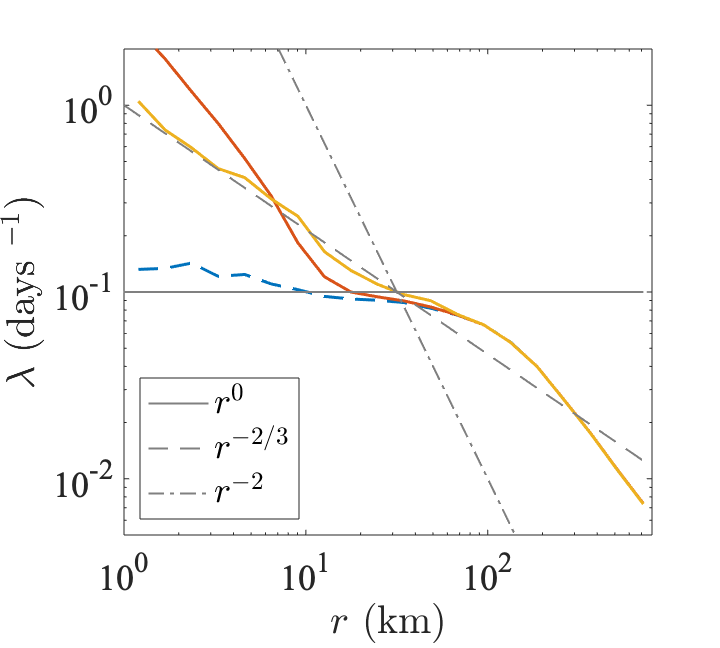

% FSLE plot for time model
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters') 

m(1) = loglog(dist_axis/1e3, fsle_mod_orig, '--', 'linewidth',1.5);
hold all 
m(2) = loglog(dist_axis/1e3, fsle_mod_time, '-', 'linewidth',1.5);
m(3) = loglog(dist_axis/1e3, fsle_mod_space, '-', 'linewidth',1.5);

r0 = loglog(dist_axis/1e3, dist_axis./dist_axis*0.1, '-','color', [0.5 0.5 0.5], 'linewidth',1);  
r23 = loglog(dist_axis/1e3, 100*dist_axis.^(-2/3), '--', 'color', [0.5 0.5 0.5], 'linewidth',1); 
r2 = loglog(dist_axis/1e3, 1e8*dist_axis.^(-2), '-.', 'color', [0.5 0.5 0.5], 'linewidth',1); 

A = legend([ r0, r23, r2], ...
    {'$r^{0}$', '$r^{-2/3}$', '$r^{-2}$'} ...
    , 'Interpreter','Latex', 'location','southwest', 'fontsize',18);

set(gca, 'fontsize', 18, 'fontname','times') 

axis([1 800 50*1e-4 2])

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$\lambda$ (days $^{-1}$)', 'Interpreter','Latex')
print('NIWs_FSLE.eps', '-depsc', '-r400')

## Frequency Spectrum

[F_orig, SPP_orig, SNN_orig, SPN_orig] = spec_pairs(mod_sep_orig,1);

SLEPTAP calculating tapers of length 120.


[F_time, SPP_time, SNN_time, SPN_time] = spec_pairs(mod_sep_time,1);

SLEPTAP calculating tapers of length 120.


[F_space, SPP_space, SNN_space, SPN_space] = spec_pairs(mod_sep_space,1);

SLEPTAP calculating tapers of length 120.


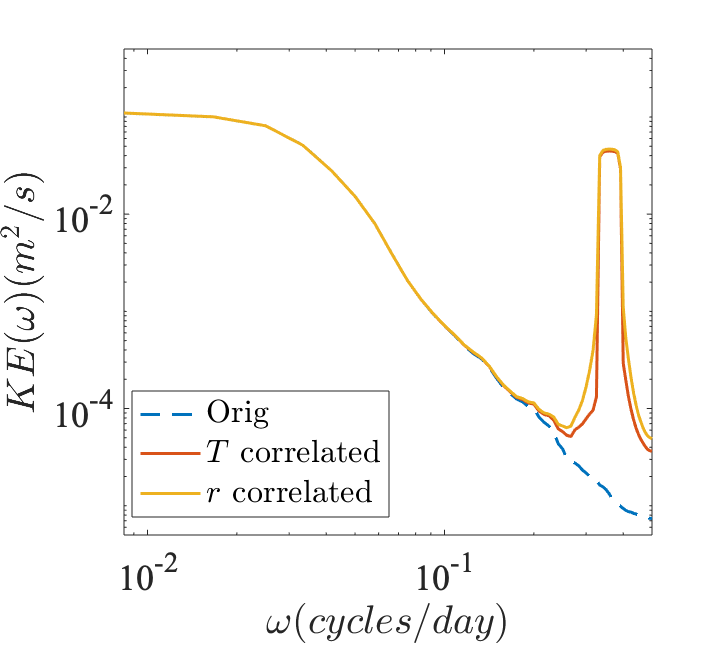

% deep figure
clear h g 
%figure('rend','painters','pos',[10 10 800 600])
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters')
        
g(1) = loglog(F_orig, nanmean(SPP_orig + SNN_orig,2),'--', 'linewidth',1.5,'color',colors(1,:));
hold all 
g(2) = loglog(F_orig, nanmean(SPP_time + SNN_time,2),'-', 'linewidth',1.5,'color', colors(2,:));
g(3) = loglog(F_orig, nanmean(SPP_space + SNN_space,2), '-', 'linewidth',1.5,'color', colors(3,:));

legend('Orig', '$T$ correlated','$r$ correlated', ...
    'location', 'best','interpreter','Latex')

set(gca, 'fontsize', 18, 'fontname', 'times') 
xlabel('$\omega (cycles/day)$','Interpreter',"latex")
ylabel('$KE (\omega) (m^2/s)$','Interpreter',"latex")

xlim([1/120, 1/2])
ylim([5e-6, 0.5])
print('NIWs_freq.eps', '-depsc', '-r400')

## Structure Function

S2ll_orig = S2ll_model(mod_sep_orig.sep, dist_bin);
S2ll_time = S2ll_model(mod_sep_time.sep, dist_bin);

S2ll_space = S2ll_model(mod_sep_space.sep, dist_bin);

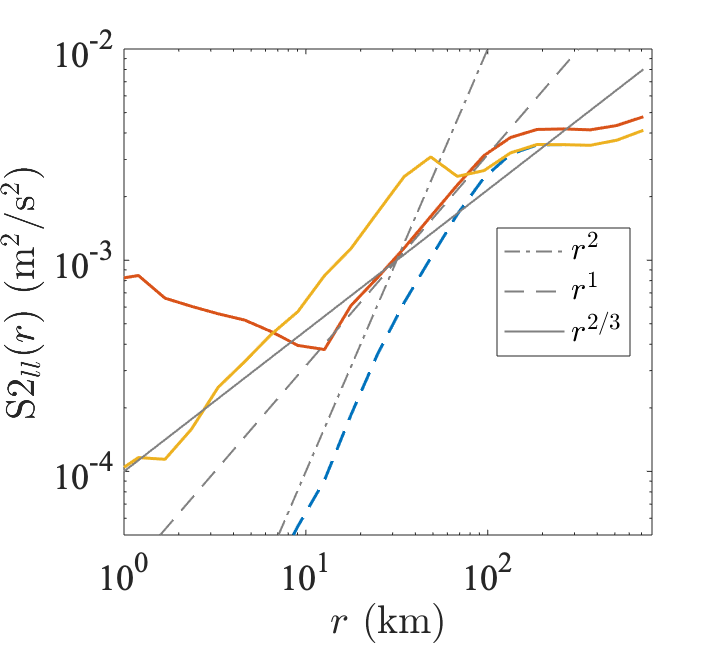

% deep figure
clear h g 
%figure('rend','painters','pos',[10 10 800 600])
figure('unit','inches','pos',[0. 0. 5, 4.5], 'renderer','painters')
        
g(1) = loglog(dist_axis/1e3, S2ll_orig,'--', 'linewidth',1.5,'color',colors(1,:));
hold all
g(2) = loglog(dist_axis/1e3, S2ll_time, '-', 'linewidth',1.5,'color', colors(2,:));
g(3) = loglog(dist_axis/1e3, S2ll_space, '-', 'linewidth',1.5,'color', colors(3,:));

r23 = loglog(dist_axis/1e3, 1e-6*dist_axis.^(2/3), '-','color', [0.5 0.5 0.5], 'linewidth',1.);
r1 =loglog(dist_axis/1e3, 10^(-7.5)*dist_axis.^(1), '--','color', [0.5 0.5 0.5], 'linewidth',1.);
r2 =loglog(dist_axis/1e3, 1e-12*dist_axis.^(2), '-.','color', [0.5 0.5 0.5], 'linewidth',1.);

A = legend([r2, r1, r23], ...
    {  '$r^{2}$', '$r^{1}$', '$r^{2/3}$'} ...
    , 'Interpreter','Latex', 'location','best');

set(gca, 'fontsize', 18, 'fontname', 'times') 

axis([1 800 5e-5 1e-2])
xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('S2$_{ll} (r)$ (m$^{2}$/s$^{2}$)', 'Interpreter','Latex')

print('NIWs_S2.eps', '-depsc', '-r400')

## Dispersion

ndays=100;
disp_orig = rel_disp(mod_sep_orig.sep, ndays);
disporig = disp_orig.avdisp/1e6;

disp_time = rel_disp(mod_sep_time.sep, ndays);
disptime = disp_time.avdisp/1e6;
disp_space = rel_disp(mod_sep_space.sep, ndays);
dispspace = disp_space.avdisp/1e6;

T=[0:99];

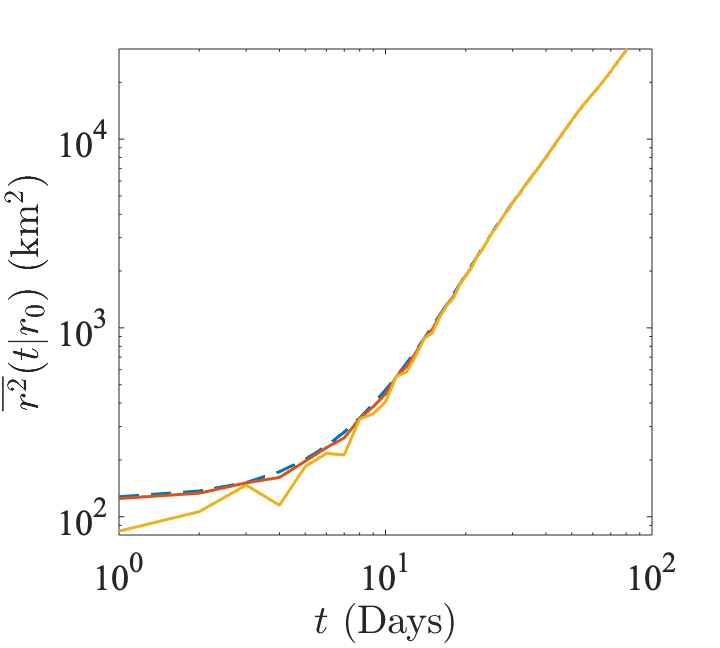

clear h g
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')
j=1;

loglog(T, disporig, '--', 'color', colors(1,:), 'linewidth', 1.5)
hold all
loglog(T, disptime, '-', 'color', colors(2,:), 'linewidth', 1.5)
loglog(T, dispspace, '-', 'color', colors(3,:), 'linewidth', 1.5)

axis([1 100 0.8*10^2 3*10^4])

set(gca,'FontSize', 18,'fontname','times')
xlabel('$t$ (Days)', 'Interpreter','Latex') 
ylabel('$\overline{r^2}(t| r_0)$ (km$^2$)', 'Interpreter','Latex')
print('NIWs_disp.eps', '-depsc', '-r400')

## Relative Diffusivity

mod_sep_orig_4_rd = model_sep_calcs_w_NIWs(mod_traj, [0,50]*1e3,0,0,0,0,0);

rd_orig_1 = rel_diff_inst_model(mod_sep_orig_4_rd.sep, dist_bin,1); 
rd_orig_6 = rel_diff_inst_model(mod_sep_orig_4_rd.sep, dist_bin,6); 

mod_sep_time_4_rd = model_sep_calcs_w_NIWs(mod_traj, [0,50]*1e3, f, 1.5/110,1.5/110, 1/20, 1);

rd_time_1 = rel_diff_inst_model(mod_sep_time_4_rd.sep, dist_bin,1); 
rd_time_6 = rel_diff_inst_model(mod_sep_time_4_rd.sep, dist_bin,6); 

mod_sep_space_4_rd = model_sep_calcs_w_NIWs(mod_traj, [0,50]*1e3, ...

mod_sep_space_4_rd = struct with fields:
    sep: [1×9168 struct]


                     f, 1.5/110, (3.0/110)/(50e3^(0.5)), 0.5, 3, 50e3)

rd_space_1 = rel_diff_inst_model(mod_sep_space_4_rd.sep, dist_bin,1); 
rd_space_6 = rel_diff_inst_model(mod_sep_space_4_rd.sep, dist_bin,6); 

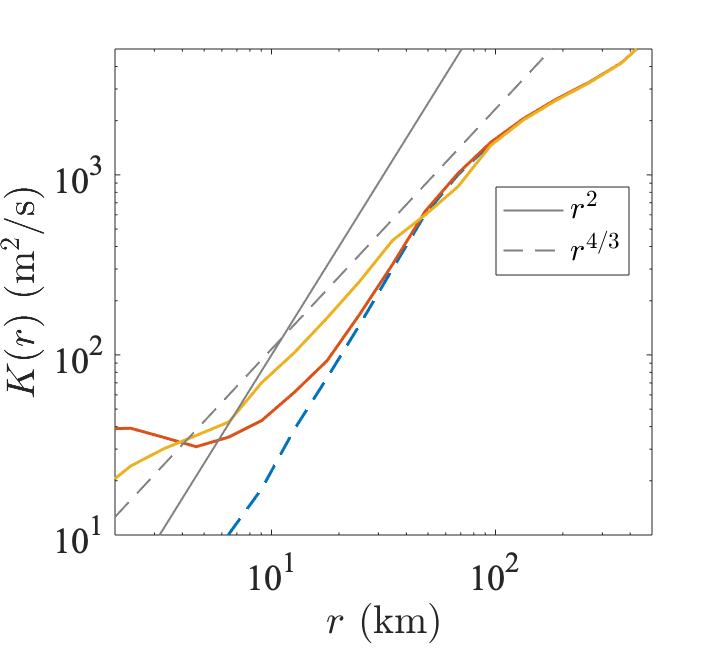

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')

g(1) = loglog(dist_axis/1e3, rd_orig_1.rdmean,'--', 'linewidth',1.5,'color', colors(1,:));
hold all 
g(2) = loglog(dist_axis/1e3, rd_time_1.rdmean,'-', 'linewidth',1.5,'color', colors(2,:));
g(3) = loglog(dist_axis/1e3, rd_space_1.rdmean,'-', 'linewidth',1.5,'color', colors(3,:));


r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


A = legend([r2, r43], ...
    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('NIWs_diff1.eps', '-depsc', '-r400')

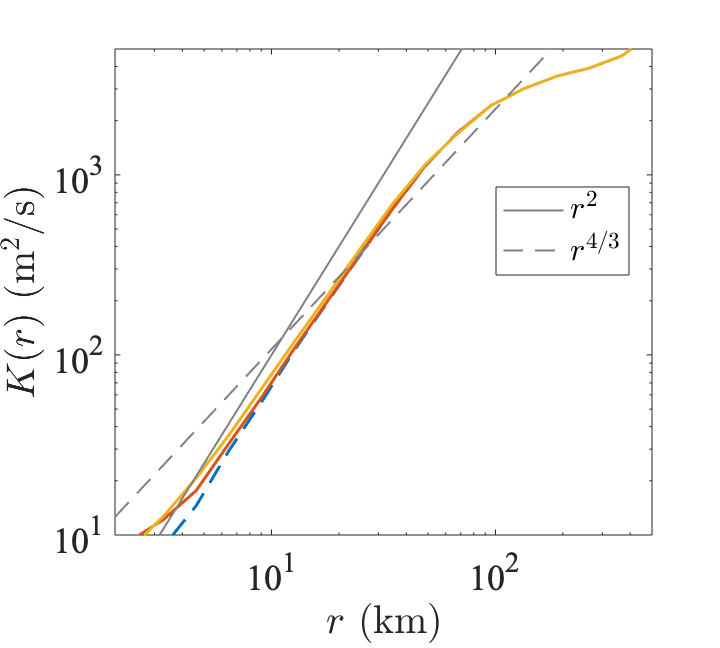

clear h g 
figure('unit','inches','pos',[0. 0., 5, 4.5], 'renderer','painters')

g(1) = loglog(dist_axis/1e3, rd_orig_6.rdmean,'--', 'linewidth',1.5,'color', colors(1,:));
hold all 
g(2) = loglog(dist_axis/1e3, rd_time_6.rdmean,'-', 'linewidth',1.5,'color', colors(2,:));
g(3) = loglog(dist_axis/1e3, rd_space_6.rdmean,'-', 'linewidth',1.5,'color', colors(3,:));


r2 = loglog(dist_axis/1e3, 1e-6*dist_axis.^2, '-','color', [0.5 0.5 0.5], 'linewidth',1);
r43 = loglog(dist_axis/1e3, 5e-4*dist_axis.^(4/3), '--','color', [0.5 0.5 0.5], 'linewidth',1);


A = legend([r2, r43], ...
    {'$r^{2}$', '$r^{4/3}$'}, 'location', 'best' ...
    , 'Interpreter','Latex');
%legend boxoff
%set(A, 'location','best') 

axis([2 500 10 5e3])
set(gca, 'fontsize', 18, 'fontname','times') 

xlabel('$r$ (km)', 'Interpreter', 'Latex') 
ylabel('$K (r)$ (m$^{2}/$s)', 'Interpreter','Latex')
print('NIWs_diff6.eps', '-depsc', '-r400')

## Functions

function [F, SPP, SNN, SPN] = spec_pairs(sep, dT)
len = 120/dT;
psi = sleptap(len);
npairs  = length(sep.sep);
CV = zeros(len, 2*npairs);

n=1;
for i = 1:npairs
    CV(:,n) = sep.sep(i).U1(1:len) + sqrt(-1)*sep.sep(i).V1(1:len);
    n=n+1;
    CV(:,n) = sep.sep(i).U2(1:len) + sqrt(-1)*sep.sep(i).V2(1:len);
    n=n+1;
end

[F, SPP, SNN, SPN] = mspec(dT, CV, psi,'cyclic');

end
